% repropdues Fleeeman figure 2.30

% properties
delta_LE = deg2rad(10.01);
delta_LE = deg2rad([90,20,10,5]);
Lambda_LE = deg2rad(45);
t_mac = convlength(.585,"in","m"); % max thickness of mean aerodynamic cord in 
b = convlength(32.2,"in","m");
S_ref = convlength(convlength(50.26,"in","m"),"in","m"); % refrence area in m^2
S_surface = convlength(convlength(367,"in","m"),"in","m");% assumed the same from figure 2.29
n_surface = 2;
c_mac = convlength(1.108,"ft","m"); % assumed the same from figure 2.29
alt = convlength(2E4,"ft","m");

[~, a, ~, rho] = atmosisa(alt); % get gas properties at altitude

% set up loop variables 
nPoints = 1000

nPoints = 1000

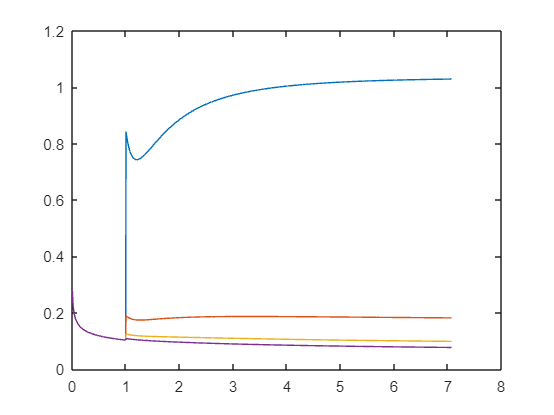

M = linspace(0, 5/cos(pi/4), nPoints);
C_D_0_surface = zeros(length(delta_LE),nPoints);
C_D_0_surface_wave = zeros(length(delta_LE),nPoints);

for i = 1:nPoints
    v = M(i) * a; % compute velocity
    q = 1/2 * rho * v^2;
    C_D_0_surface(:,i) = dragCoeff_zeroLift_surface(M(i), q, n_surface, c_mac, delta_LE, Lambda_LE, t_mac, b, S_surface, S_ref);
    for j = 1:length(delta_LE)
        C_D_0_surface_wave(j,:) = dragCoeff_wave_surface(M, n_surface, delta_LE(j), Lambda_LE, t_mac, b, S_ref);
    end
end

plot(M, C_D_0_surface);


M_Lambda_LE = M * cos(Lambda_LE);
semilogy(M_Lambda_LE, C_D_0_surface_wave / (n_surface*cos(Lambda_LE)*t_mac*b/S_ref) );

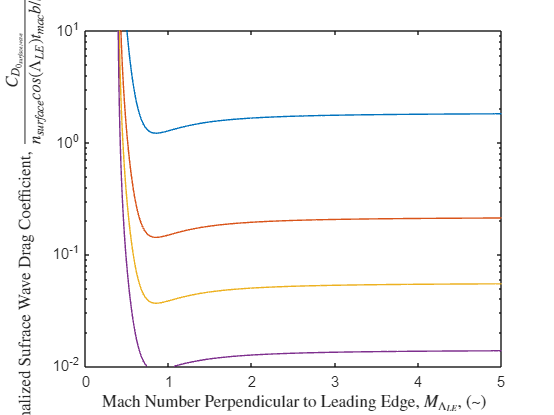

xlim([0,5]); ylim([.01,10]);
xlabel("Mach Number Perpendicular to Leading Edge, $M_{\Lambda_{LE}}$, (~)", "Interpreter","latex");
ylabel("Normalized Sufrace Wave Drag Coefficient, $\frac{C_{D_{0_{surface,wave}}}} {n_{surface} cos(\Lambda_{LE}) t_{mac} b/S_{ref}}$, (~)", "Interpreter","latex");